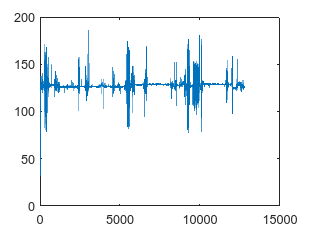

T = readtable('CR1000XSeries_BuoyData.dat');


T.TIMESTAMP(5);
plot(T.t_on./T.period*255)

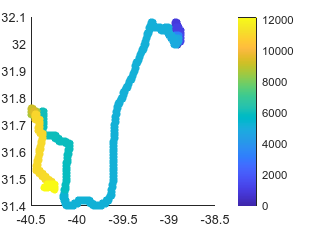

scatter(T.Longitude_B, T.Latitude_B, [], T.RECORD, 'fill')
colorbar()

%6083-11092 At stony
start_record = 6083;
stop_record = 11092;
start_time = T.TIMESTAMP(start_record);
stop_time = T.TIMESTAMP(stop_record);

mask = T.RECORD>start_record & T.RECORD<stop_record;
sum(mask)

ans = 5008

T2 = T(mask,:);

The logical indices in position 1 contain a true value outside of the array bounds.

plot(T2.RECORD, T2.t_on./T2.period*255)
plot(T2.TIMESTAMP, T2.Humidity)
plot(T2.TIMESTAMP, T2.Temperature)
plot(T2.RECORD, T2.PAR)

%9066-9426 In Water
start_record = 9066;
stop_record = 9324;

start_idx = find(T.RECORD == start_record);

Dot indexing is not supported for variables of this type.

stop_idx = find(T.RECORD == stop_record);

start_time = T.TIMESTAMP(start_idx);
stop_time = T.TIMESTAMP(stop_idx);

mask = T.RECORD>start_record & T.RECORD<stop_record;

T5 = T(mask,:); % Filtered full data

The logical indices in position 1 contain a true value outside of the array bounds.


T3 = readtable('CR1000XSeries_PWMData.dat');
t_mask = T3.TIMESTAMP>start_time & T3.TIMESTAMP<stop_time;
T4 = T3(t_mask,:); % Filtered PWM data
pwm = T4.t_on./T4.period*255;
accel = T4.t_on./T4.period*9.8*2;
plot(T4.TIMESTAMP,accel)

%unique(milliseconds(diff(T4.TIMESTAMP)))
%accel = accel.^2

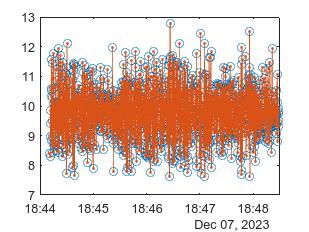

fs = 5;

%[y,ty] = resample(accel,T4.TIMESTAMP,fs,3 ,1);
[y,ty] = resample(accel,T4.TIMESTAMP,fs,1,1); % Adjust "smoothness" with upsampling
plot(T4.TIMESTAMP,accel,'o',ty,y,'.-')

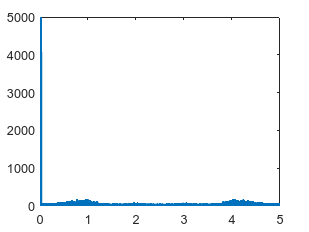

period = 1/fs;             % Sampling period       
ts = seconds(T4.TIMESTAMP(end) - T4.TIMESTAMP(1));
L = ts./period +1; % Length of signal
t = (0:L-1)*period;        % Time vector

result = fft(y);
fs/L*(0:L-1);
plot(fs/L*(0:L-1),abs(result),"LineWidth",3)
ylim([0,5000])

% Theoretical E(f) based on wind speed = 10mph
v = 4.4704; % 10 mph
C_d = 1.2e-3;
u = sqrt(C_d*v);

f = fs/L*(0:L-1);

theoretical_spectra = (2*pi*0.012*2.5*9.8*u.*f.^(-4))/8*pi.^4;



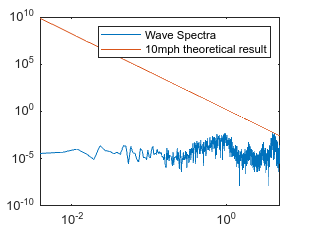

s_aa = 2*result.*conj(result)./(ts.*fs^2);
loglog(f,s_aa/(2*pi.*fs)^2, DisplayName="Wave Spectra")
hold on
loglog(f, theoretical_spectra, DisplayName="10mph theoretical result")
%xlim([0.1,2.5])
%ylim([10e-3,10e0])
legend()
hold off

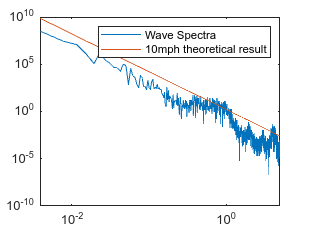

loglog(f,(abs(result).^2)./(2.*pi.*f').^4, DisplayName="Wave Spectra")
hold on
loglog(f, theoretical_spectra, DisplayName="10mph theoretical result")
%xlim([0.1,2.5])
%ylim([10e-4,10e1])
legend()
hold off

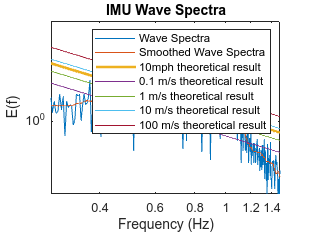

spectra = (abs(result).^2)./(2.*pi.*f').^4;
loglog(f,spectra, DisplayName="Wave Spectra")

hold on
loglog(f,medfilt1(spectra,30), DisplayName="Smoothed Wave Spectra")

loglog(f, theoretical_spectra, DisplayName="10mph theoretical result", linewidth=2)

v = 0.1; % 10 mph
u = sqrt(C_d*v);
computed_spectra = (2*pi*0.012*2.5*9.8*u.*f.^(-4))/8*pi.^4;
loglog(f, computed_spectra, DisplayName="0.1 m/s theoretical result")

v = 1; % 10 mph
u = sqrt(C_d*v);
computed_spectra = (2*pi*0.012*2.5*9.8*u.*f.^(-4))/8*pi.^4;
loglog(f, computed_spectra, DisplayName="1 m/s theoretical result")

v = 10; % 10 mph
u = sqrt(C_d*v);
computed_spectra = (2*pi*0.012*2.5*9.8*u.*f.^(-4))/8*pi.^4;
loglog(f, computed_spectra, DisplayName="10 m/s theoretical result")

v = 100; % 10 mph
u = sqrt(C_d*v);
computed_spectra = (2*pi*0.012*2.5*9.8*u.*f.^(-4))/8*pi.^4;
loglog(f, computed_spectra, DisplayName="100 m/s theoretical result")

xlim([0.1,2.5])
%ylim([10e-3,10e0])
legend()
ylabel("E(f)")
xlabel("Frequency (Hz)")
title("IMU Wave Spectra")
hold off

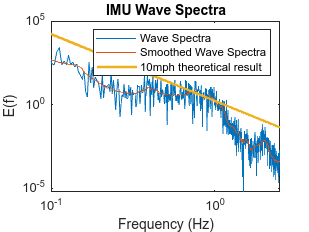

loglog(f,spectra, DisplayName="Wave Spectra")
hold on
loglog(f,medfilt1(spectra,30), DisplayName="Smoothed Wave Spectra")
loglog(f, theoretical_spectra, DisplayName="10mph theoretical result", linewidth=2)

xlim([0.1,2.5])
%ylim([10e-3,10e0])
legend()
ylabel("E(f)")
xlabel("Frequency (Hz)")
title("IMU Wave Spectra")
hold off

ans = 1.0e+08 *

       Inf
    3.2472
    0.2785
    0.1179
    0.0112
    0.0012
    0.0174
    0.0027
    0.0013
    0.0005


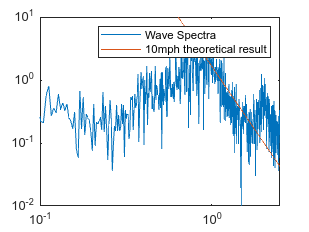

loglog(f,abs(result)/(2*pi.*fs), DisplayName="Wave Spectra")
hold on
loglog(f, theoretical_spectra, DisplayName="10mph theoretical result")
xlim([0.1,2.5])
ylim([10e-3,10e0])
legend()
hold off

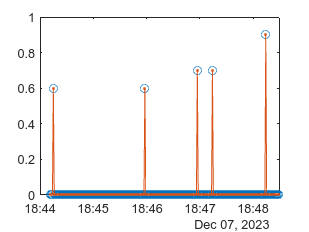

%fs = 1;
%[y,ty] = resample(accel,T4.TIMESTAMP,fs,3 ,1);
%[y2,ty2] = resample(T5.Speed,T5.TIMESTAMP,fs,1,1); % Adjust "smoothness" with upsampling
plot(T5.TIMESTAMP,T5.Speed,'o',ty2,y2,'.-')

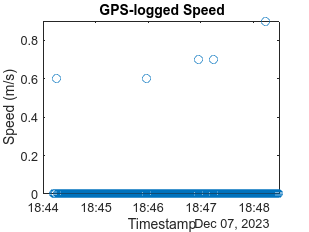

plot(T5.TIMESTAMP,T5.Speed,'o')
xlabel("Timestamp")
ylabel("Speed (m/s)")
title("GPS-logged Speed")

humidity = median(T5.Humidity)*0.0375-37.7 % percent

% Absolute humidities
% 59.9125% @ 43.2 F
% 100% @ 43.2 F
q_a = 0.004413;
q_s = 0.007366;

par = median(T5.PAR) % watts

par = 16.1900

a = 8.54942e-4;
b = 2.57305e-4;
c = 1.65368e-7;

% measured temperature (volts)
t_V = median(T5.Temperature)/1000;
% measured temperature (resistance)
t_R = t_V*10000/(5-t_V);

% Convert to temperature
air_temp_K = 1/(a+b*log(t_R)+c*(log(t_R))^3)% - 273.15

air_temp_K = 272.3288

surface_temp_K = 279.372 %43.2 F

surface_temp_K = 279.3720

wind_speed = 4.4704; % 10 MPH

F_lon_up = 0.96*(5.67e-8)*surface_temp_K^4

F_lon_up = 331.5781

F_lon_down = 0.746*(1.26)*(5.67e-8)*air_temp_K^4

F_lon_down = 293.1342

Q_s = 1.3*1003*(1.2e-3)*wind_speed*(air_temp_K-surface_temp_K)

Q_s = -49.2656


Q_l = 1.3*(2.5e6)*(1.2e-3)*wind_speed*(q_a-q_s)

Q_l = -51.4843


% Net
-F_lon_up + F_lon_down + Q_s + Q_l + par

ans = -123.0038

0.08/(max(accel) - min(accel))

ans = 0.0154